## Problem 1 

Please use spectral clustering to segment the image `clemson.jpeg'.

% Load the image
image = imread('clemson.jpeg');

% Downsample the image
scaleFactor = 0.8; % for example, adjust based on your needs
smallImage = imresize(image, scaleFactor);

[rows, cols, ~] = size(smallImage); % 'image' is the original RGB image
pixels = reshape(smallImage, rows*cols, 3); % Reshape into 2D matrix for clustering


Create Adjacency Matrix using K-Nearest Neighbor Graph with Gaussian Similarity

sigma = 0.2; % sigma
% Use the knnsearch function to find the k-nearest neighbors
k = 10; % KNN
[neighbors, distances] = knnsearch(double(pixels), double(pixels), 'K', k+1);

% Create the sparse adjacency matrix
rowIdx = repmat((1:size(pixels, 1))', 1, k);
colIdx = neighbors(:, 2:end); % exclude the first column which is the point itself
values = exp(-distances(:, 2:end).^2 / (2*sigma^2));
adjacencyMatrix = sparse(rowIdx, colIdx, values, size(pixels, 1), size(pixels, 1));

Create Laplacian Matrix using Adjacency and Degree Matrix

#### ***L = D - A***

% Construct the degree matrix
degreeMatrix = diag(sum(adjacencyMatrix));

laplacianMatrix = degreeMatrix - adjacencyMatrix;

Perform Eigen Value Decomposition

[eigVectors, eigValues] = eigs(laplacianMatrix);

Sort and select Eigen vectors for clustering

k = 2; % No of Clusters

% Find the sorted eigenvalues and their indices
[eigValuesSorted, idx] = sort(diag(eigValues));

% Find the indices of the first two non-zero eigenvalues
% Assuming the first eigenvalue is zero or near-zero, we skip it
idxNonZero = idx(eigValuesSorted > eps);

% Select the first k non-zero eigenvectors
selectedEigVectors = eigVectors(:, idxNonZero(1:k));

Normalize the rows

% Calculate the norm of each row
rowNorms = sqrt(sum(selectedEigVectors.^2, 2));

% Divide each row by its norm (avoid division by zero)
normalizedEigVectors = selectedEigVectors ./ (rowNorms + eps);

Apply the Clustering Algorithm

clusters = kmeans(normalizedEigVectors, k);

% Reshape Clusters
segmentedImage = reshape(clusters, rows, []);

Display the Image

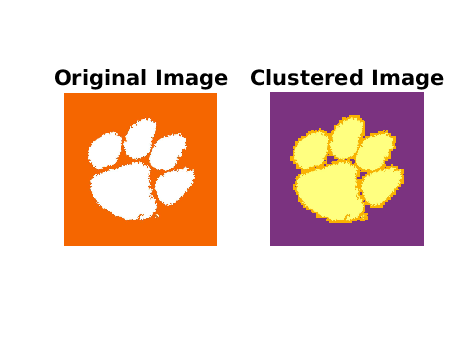

newImage = labeloverlay(smallImage, segmentedImage);

% Display the original image and the color-coded cluster overlay
figure;
subplot(1,2,1), imshow(smallImage), title('Original Image');
subplot(1,2,2), imshow(newImage), title('Clustered Image');